clearvars;
%inputs
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 0.2;
yint = 0.2;
zint = 0.2;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
datasize = xtotal*ytotal*ztotal;
lsberr = 67626;

mu_0 = 4*pi*10^-7; % T m/A^2
diameter = 4.98; %m
length = 1.97; %m
Br = 14800/10000; %T
V = (diameter/2)^2*pi*length; %m^3
dipole_moment = Br * V / mu_0; %A m^2
M_0 = dipole_moment/V; %A/m
B_t = mu_0*V*M_0/(4*pi); %T m^3

sensor = [0, 0, -25];
lsb = 0.008/1000; %mT
H_0 = repelem([0 0 1], [datasize], [1]);

davg = importdata('C:\Users\Brandon Nguyen\Documents\GitHub\magnetic-sensor-data\PIM_03022023\DataAvg.txt'); %mT
davg.data;
davg1 = davg.data(:,2:7);
dataavg= sortrows(davg1, [3 2 1]);
datamode = importdata('C:\Users\Brandon Nguyen\Documents\GitHub\magnetic-sensor-data\PIM_03022023\DataMode.txt'); %mT

lsberror = {};
z = zmin;
locpred = [];
Bpred = [];

for k = 1:ztotal
    zstr = sprintf('%.1f', z);
    y = ymin;

    for j = 1:ytotal
        ystr = sprintf('%.1f', y);
        x = xmin;

        for i = 1:xtotal
%             location = [location; x y z];
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\GitHub\magnetic-sensor-data\PIM_03022023\',xstr,'_',ystr,'_',zstr,'.data');
%             test = parquetread(filename);
%             
%             b_x = test.Magnetometerx;
%             xmode1 = mode(b_x);
%             b_x(b_x==xmode1) = NaN;
%             xmode2 = mode(b_x);
%             xerr = abs(xmode2-xmode1);
% 
%             b_y = test.Magnetometery;
%             ymode1 = mode(b_y);
%             b_y(b_y==ymode1) = NaN;
%             ymode2 = mode(b_y);
%             yerr = abs(ymode2-ymode1);
% 
%             b_z = test.Magnetometerz;
%             zmode1 = mode(b_z);
%             b_z(b_z==zmode1) = NaN;
%             zmode2 = mode(b_z);
%             zerr = abs(zmode2-zmode1);
%             datamode = [datamode; [xmode1 ymode1 zmode1]];

%             
% 
%             syms a b c;
%             eqns = [3*(-1-c)*(-a)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 == xmode1, ...
%                 3*(-1-c)*(-b)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 == ymode1, ...
%                 3*(-1-c)*(-1-c)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 - 1/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^3 == zmode1];
%             S = solve(eqns, 'Real', true);
%             xmat = vpa(S.a);
%             ymat = vpa(S.b);         
%             zmat = vpa(S.c);
%             locmat = [xmat ymat zmat]
%             mask = any(imag(locmat),2);
%             locmat(mask,:)=[];
%             locmat = [xmat ymat zmat];
%             if size(locmat, 1) > 1
%                 locpred = [locpred; mean(locmat)];
%             else
%                 locpred = [locpred; locmat];
%             end
%             
%             magnet = [x y z];
%             R = norm(magnet - sensor);
%             Bx = B_t*3*(magnet(3)-sensor(3))*(magnet(1)-sensor(1))/R^5;
%             By = B_t*3*(magnet(3)-sensor(3))*(magnet(2)-sensor(2))/R^5;
%             Bz = B_t*3*(magnet(3)-sensor(3))*(magnet(3)-sensor(3))/R^5 + 1/R^3;
%             Bpred = [Bpred; [Bx, By, Bz]];
% 
%             x = x + xint;
%             if isnan(xerr) && isnan(yerr) && isnan(zerr)
%                 x = x + xint;
%             elseif xerr > lsb
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror; loc];
%                 x = x + xint;
%             elseif yerr > lsb
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror; loc];
%                 x = x + xint;
%             elseif zerr > lsb
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror; loc];
%                 x = x + xint;
%             else
%                 x = x + xint;
%             end
        end
        y = y + yint;
    end
    z = z + zint
end

z =           0.2


z =           0.4


z =           0.6


z =           0.8


z =      1


z =           1.2


z =           1.4


z =           1.6


z =           1.8


z =             2


z =           2.2


z =           2.4


z =           2.6


z =           2.8


z =             3


z =           3.2


z =           3.4


z =           3.6


z =           3.8


z =             4


z =           4.2


z =           4.4


z =           4.6


z =           4.8


z =             5


z =           5.2


%B = B_t*(3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)*10^12;
% B_t = Br*V/(4*pi);
X = sensor - dataavg(:,1:3);
R = sqrt(sum(X.^2, 2));
B_not = (3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)*10^12;
xfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-x(:,1))./R.^5)*10^12;
beta0 = [10^-12];
mdlx = fitnlm(dataavg(:,1:3), dataavg(:,4), xfieldfun, beta0)

mdlx = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
           Estimate         SE         tStat      pValue 
          __________    __________    ________    _______

    b1    -6.395e-11    1.9779e-10    -0.32332    0.74645


Number of observations: 67626, Error degrees of freedom: 67625
Root Mean Squared Error: 0.27
R-Squared: -0.000227,  Adjusted R-Squared -0.000227
F-statistic vs. zero model: 0.105, p-value = 0.746

yfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-x(:,2))./R.^5)*10^12;
mdly = fitnlm(dataavg(:,1:3), dataavg(:,5), yfieldfun, beta0)

mdly = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
           Estimate          SE         tStat      pValue 
          ___________    __________    _______    ________

    b1    -3.8476e-10    1.8776e-10    -2.0492    0.040451


Number of observations: 67626, Error degrees of freedom: 67625
Root Mean Squared Error: 0.257
R-Squared: -0.445,  Adjusted R-Squared -0.445
F-statistic vs. zero model: 4.2, p-value = 0.0404

zfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-1-x(:,3))./R.^5-1./R.^3)*10^12;
mdlz = fitnlm(dataavg(:,1:3), dataavg(:,6), zfieldfun, beta0)

mdlz = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
           Estimate         SE        tStat    pValue
          __________    __________    _____    ______

    b1    -8.911e-09    2.3026e-12    -3870      0   


Number of observations: 67626, Error degrees of freedom: 67625
Root Mean Squared Error: 0.084
R-Squared: 0.896,  Adjusted R-Squared 0.896
F-statistic vs. zero model: 1.5e+07, p-value = 0

bx = table2array(mdlx.Coefficients);
by = table2array(mdly.Coefficients);
bz = table2array(mdlz.Coefficients);
B_tguess = (bx(1)+by(1)+bz(1))/3

B_tguess =   -3.1199e-09


B_guess = B_tguess.*V/(4*pi)*B_not

B_guess =        0.3018       0.3018     -0.96575
      0.29184        0.304     -0.97439
      0.28164      0.30613     -0.98276
      0.27121       0.3082     -0.99086
      0.26055      0.31018     -0.99868
      0.24968       0.3121      -1.0062
      0.23859      0.31393      -1.0134
      0.22729      0.31569      -1.0203
       0.2158      0.31736      -1.0269
      0.20413      0.31895      -1.0332


dataavg(:,4:6)

ans =      -0.57299      0.53811       1.3589
     -0.57247      0.54006       1.3602
     -0.57158      0.53834       1.3644
     -0.57191      0.53504       1.3689
     -0.57199      0.53018       1.3744
     -0.57219       0.5241       1.3805
     -0.57256      0.51752       1.3881
     -0.57297      0.50995       1.3952
     -0.57415      0.49957       1.4035
     -0.57524       0.4889       1.4134


B_guess = [dataavg(:, 1:3) B_guess];

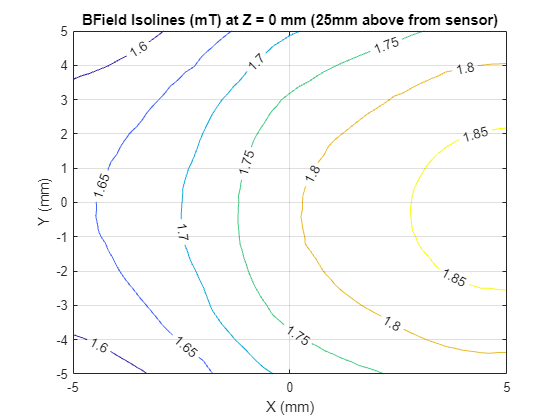

zzero = find(dataavg(:,3) == 0);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:6).^2,2));
zeroB = reshape(zeroB, [51 51]);
zerox = reshape(zzeromat(:,1), [51 51]);
zeroy = reshape(zzeromat(:,2), [51 51]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (25mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

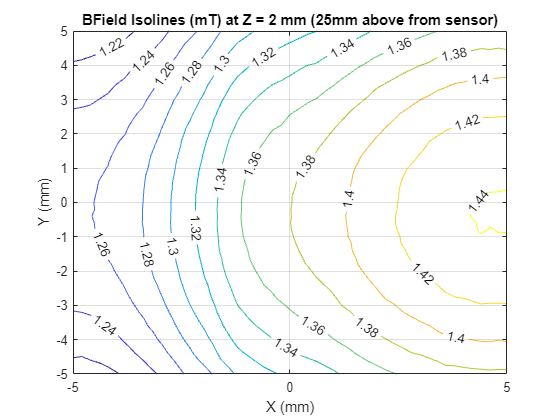


ztwo = find(dataavg(:,3) == 2);

ztwomat = dataavg(ztwo,:);
twoB = sqrt(sum(ztwomat(:,4:6).^2,2));
twoB = reshape(twoB, [51 51]);
twox = reshape(ztwomat(:,1), [51 51]);
twoy = reshape(ztwomat(:,2), [51 51]);

contour(twox, twoy, twoB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 2 mm (25mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;

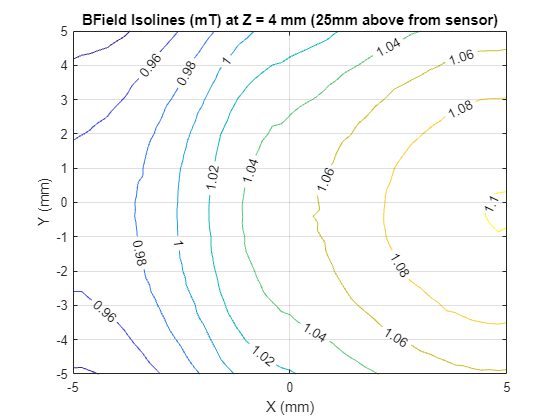


zfour = find(dataavg(:,3) == 4);

zfourmat = dataavg(zfour,:);
fourB = sqrt(sum(zfourmat(:,4:6).^2,2));
fourB = reshape(fourB, [51 51]);
fourx = reshape(zfourmat(:,1), [51 51]);
foury = reshape(zfourmat(:,2), [51 51]);

contour(fourx, foury, fourB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 4 mm (25mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;